Generate a training dataset

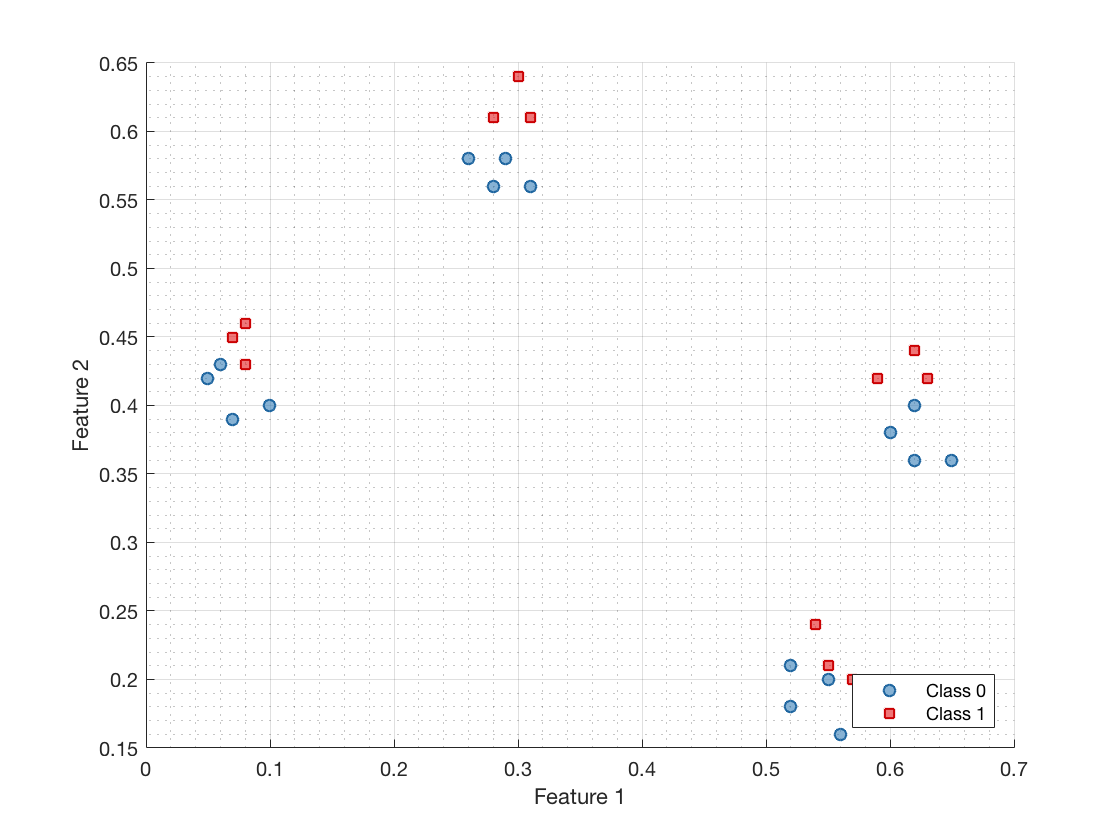

X = [0.05 0.42
0.06 0.43
0.07 0.39
0.10 0.40
0.07 0.45
0.08 0.46
0.08 0.43
0.26 0.58
0.29 0.58
0.28 0.56
0.31 0.56
0.28 0.61
0.30 0.64
0.31 0.61
0.52 0.18
0.52 0.21
0.55 0.20
0.56 0.16
0.54 0.24
0.55 0.21
0.57 0.20
0.60 0.38
0.62 0.40
0.62 0.36
0.65 0.36
0.59 0.42
0.62 0.44
0.63 0.42];
Y = [0,0,0,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,1,1,1]';
ds_train = prtDataSetClass(X,Y);
plot(ds_train)

axis equal tight

Generate a testing/validation dataset

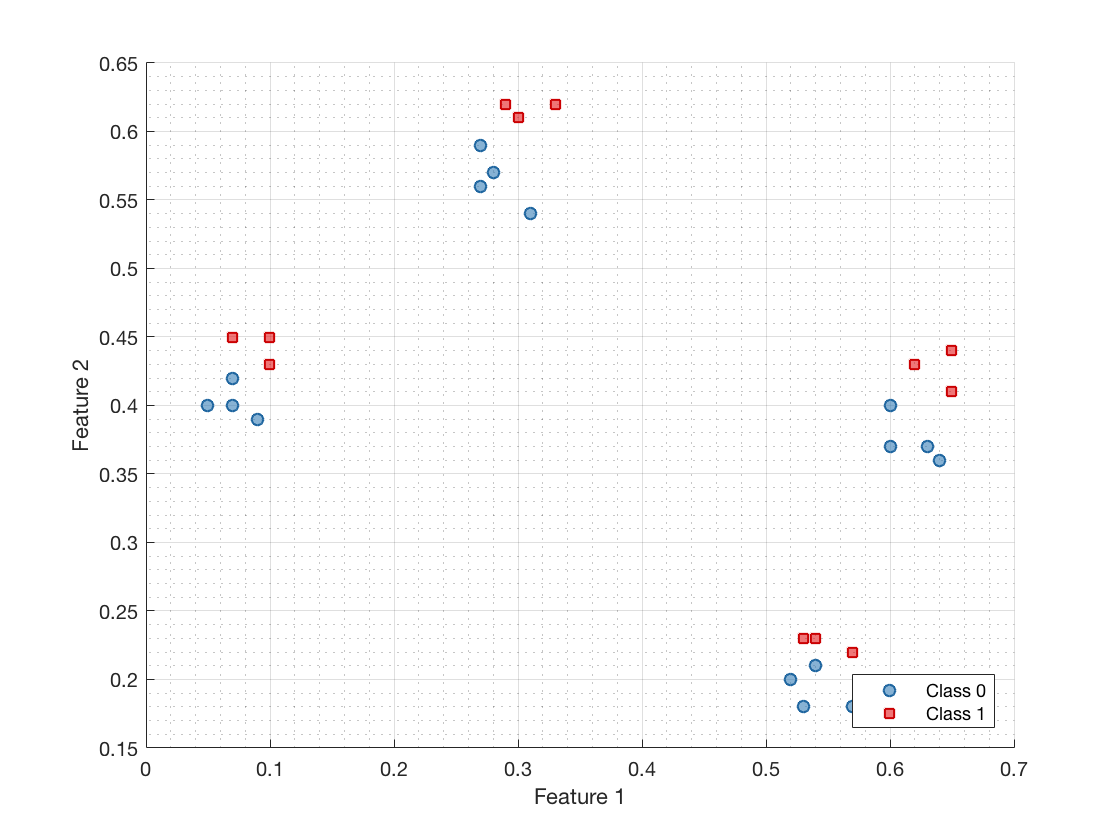

X = [0.05 0.40
0.07 0.42
0.09 0.39
0.07 0.40
0.10 0.45
0.07 0.45
0.10 0.43
0.27 0.59
0.27 0.56
0.28 0.57
0.31 0.54
0.30 0.61
0.29 0.62
0.33 0.62
0.60 0.40
0.63 0.37
0.60 0.37
0.64 0.36
0.65 0.41
0.65 0.44
0.62 0.43
0.52 0.20
0.53 0.18
0.54 0.21
0.57 0.18
0.53 0.23
0.54 0.23
0.57 0.22];
Y = [0,0,0,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,1,1,1,0,0,0,0,1,1,1]';
ds_test = prtDataSetClass(X,Y);
plot(ds_test)

axis equal tight

Build, train, and plot a KNN classifier

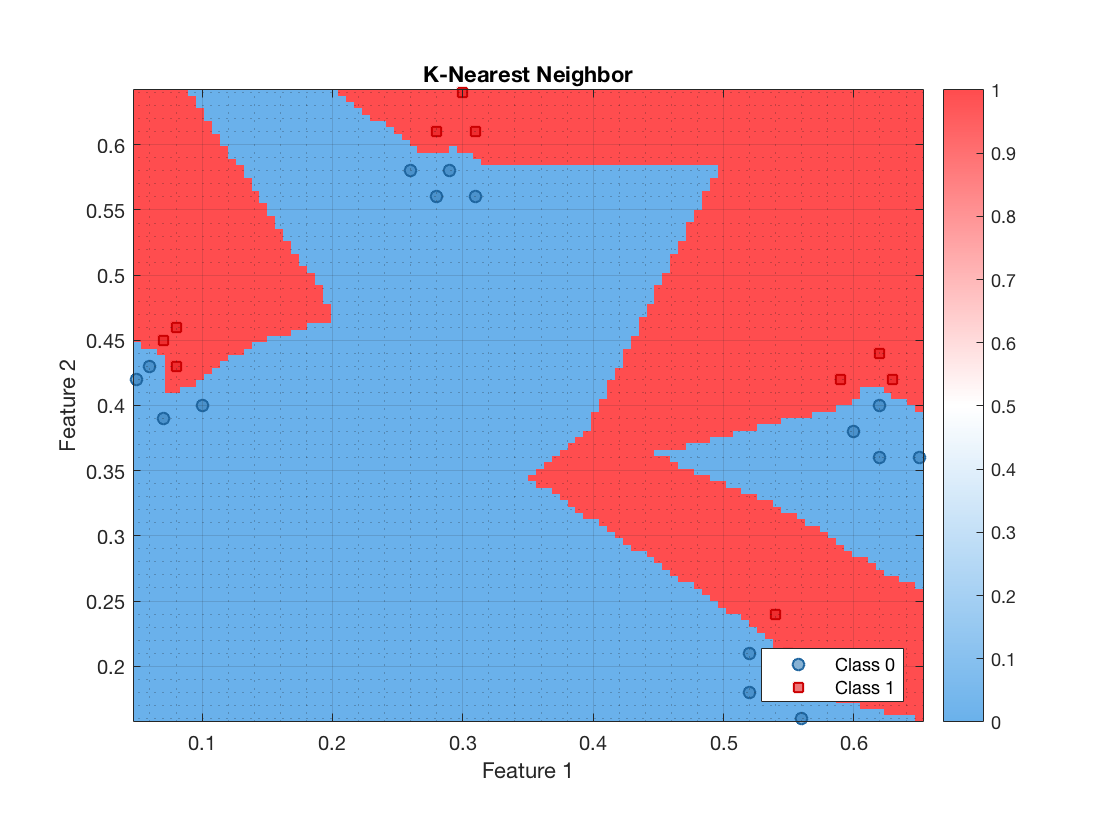

classifier = prtClassKnn('k',1);
classifier = classifier+prtDecisionBinaryMinPe;
classifier_trained = classifier.train(ds_train);
plot(classifier_trained.actionCell{1})
axis equal tight
colorbar

% the values associated with the classifier contour are the number
% of nearest neighbors that are red (Class 1)

Compute and plot the ROC curve

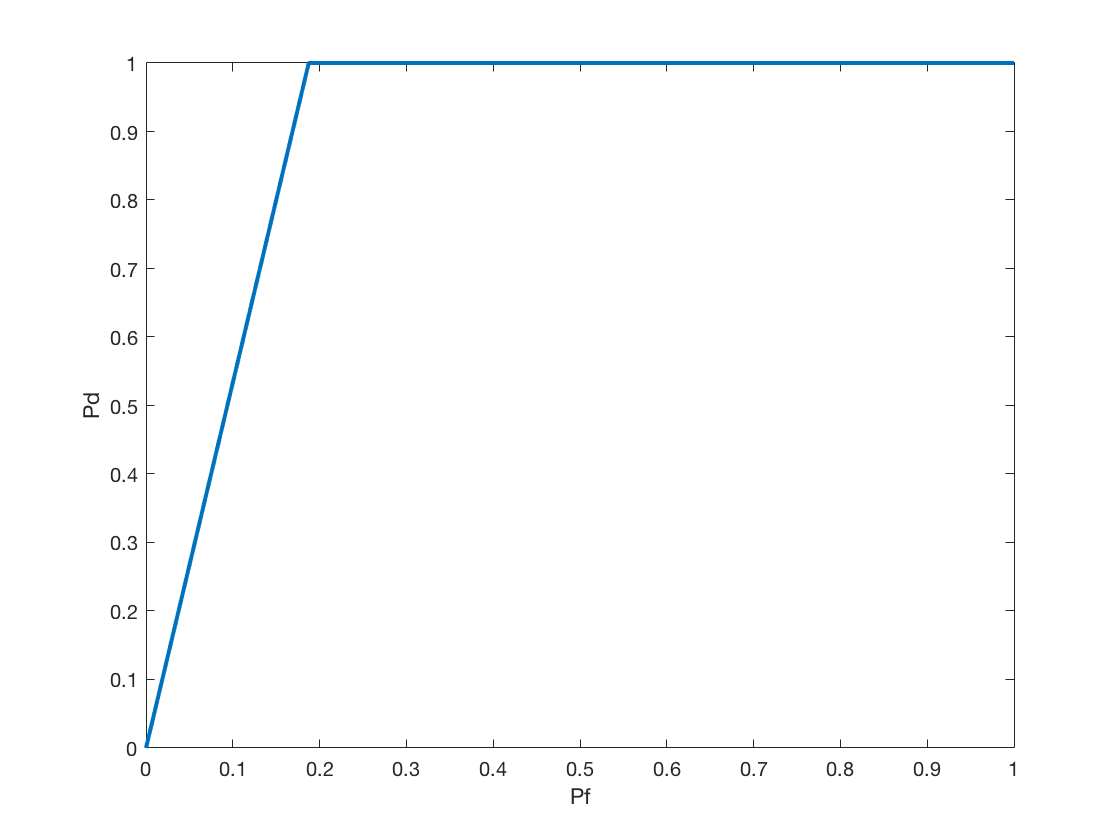

results = classifier_trained.run(ds_test);
prtScoreRoc(results)

prtScorePercentCorrect(results)

ans =    0.892857142857143
